# Option A: Comparison of Spatial Denoising Filters

Research Question: How do linear (Gaussian), non-linear (median), and hybrid (median + Gaussian) filters compare when restoring an image corrupted by mixed Gaussian and salt-and-pepper noise? **Data & Setup:** Built-in grayscale image `rice.png` (`Iref`, 256×256 uint8) degraded using `rng(42)` with additive Gaussian noise (mean 0, variance 0.01) followed by salt-and-pepper noise (density 0.02).

% Create results directory if it does not exist
if ~exist('results', 'dir')
    mkdir('results');
end

% 1. Load reference image and apply exact required degradation
Iref = imread('rice.png');
rng(42);
Id = imnoise(imnoise(Iref, 'gaussian', 0, 0.01), 'salt & pepper', 0.02);

% 2. Apply the three denoising filters
I_med = medfilt2(Id, [3 3]);                 % 3x3 Median filter
I_gauss = imgaussfilt(Id, 1.5);              % Gaussian filter (sigma = 1.5)
I_hybrid = imgaussfilt(I_med, 1.5);          % 3x3 Median -> Gaussian (sigma = 1.5)

% Save the three processed images as PNG files in results/
imwrite(I_med, fullfile('results', 'filtered_median_3x3.png'));
imwrite(I_gauss, fullfile('results', 'filtered_gaussian_sigma1_5.png'));
imwrite(I_hybrid, fullfile('results', 'filtered_hybrid_med_gauss.png'));

% Calculate PSNR and SSIM against Iref (including noisy baseline for context)
filters = {'Degraded (Baseline)'; '3x3 Median'; 'Gaussian (sigma = 1.5)'; '3x3 Median + Gaussian (1.5)'};
psnr_vals = [
    psnr(Id, Iref);
    psnr(I_med, Iref);
    psnr(I_gauss, Iref);
    psnr(I_hybrid, Iref)
    ];
ssim_vals = [
    ssim(Id, Iref);
    ssim(I_med, Iref);
    ssim(I_gauss, Iref);
    ssim(I_hybrid, Iref)
    ];

metricsTable = table(filters, round(psnr_vals, 2), round(ssim_vals, 4), ...
    'VariableNames', {'Image_or_Filter', 'PSNR_dB', 'SSIM'});

disp(metricsTable);

            Image_or_Filter            PSNR_dB     SSIM 
    _______________________________    _______    ______

    {'Degraded (Baseline)'        }     18.09     0.3696
    {'3x3 Median'                 }     25.37     0.6232
    {'Gaussian (sigma = 1.5)'     }     25.75     0.6921
    {'3x3 Median + Gaussian (1.5)'}     25.58     0.6913



writetable(metricsTable, fullfile('results', 'metrics_comparison.csv'));

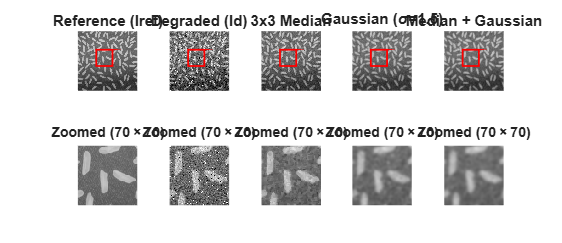

% Define a 70x70 zoomed region (>= 60x60 requirement)
r = 80:149;
c = 80:149;

fig = figure('Position', [100, 100, 1200, 520], 'Color', 'w');

titles = {'Reference (Iref)', 'Degraded (Id)', '3x3 Median', 'Gaussian (\sigma=1.5)', 'Median + Gaussian'};
imgs = {Iref, Id, I_med, I_gauss, I_hybrid};

for k = 1:5
    % Top row: Full image with crop rectangle
    subplot(2, 5, k);
    imshow(imgs{k});
    hold on;
    rectangle('Position', [c(1), r(1), length(c), length(r)], 'EdgeColor', 'r', 'LineWidth', 1.2);
    hold off;
    title(titles{k}, 'FontSize', 10);

    % Bottom row: Zoomed 70x70 crop
    subplot(2, 5, k + 5);
    imshow(imgs{k}(r, c));
    title('Zoomed (70\times70)', 'FontSize', 9);
end

exportgraphics(fig, fullfile('results', 'visual_comparison_zoom.png'), 'Resolution', 300);

## Interpretation and Limitations

Preferred Filter:Visually, the **3×3 Median + Gaussian (σ = 1.5) hybrid filter** is preferred for this mixed-noise image. Although the standalone Gaussian filter (σ = 1.5) achieves a marginally higher PSNR (25.75 dB vs. 25.58 dB) and SSIM (0.6921 vs. 0.6913), the hybrid pipeline eliminates the dark and bright impulse blotches left behind by pure Gaussian smoothing, yielding the cleanest background and grain interiors.

**Filter Behavior (Remaining Noise vs. Blur):**

- **3×3 Median Filter (25.37 dB, SSIM 0.6232):** Effectively removes isolated salt-and-pepper spikes while keeping grain edges sharp, but leaves noticeable zero-mean Gaussian graininess across the background and kernels.

- **Gaussian Filter, σ = 1.5 (25.75 dB, SSIM 0.6921):** Smooths out the Gaussian background noise, but smears extreme 0 and 255 impulse pixels into dark/bright blotches and softens grain edges.

- **3×3 Median + Gaussian, σ = 1.5 (25.58 dB, SSIM 0.6913):** Running the median filter first strips away impulse outliers before linear smoothing. The subsequent Gaussian pass suppresses residual Gaussian noise, with the trade-off of slightly stronger edge blurring than the standalone filters.

**Limitation of the Comparison:**Global full-reference metrics such as **PSNR** (based on pixel-wise MSE) and **SSIM** reward overall smoothness and fail to penalize localized impulse artifacts or task-specific edge loss. For example, if the denoised image were passed into a segmentation pipeline to count rice grains, the extra edge softening from the σ = 1.5 Gaussian stage could merge adjacent touching grains into single objects, making a sharper filter preferable despite a lower PSNR.